**Creating Continuous signal**

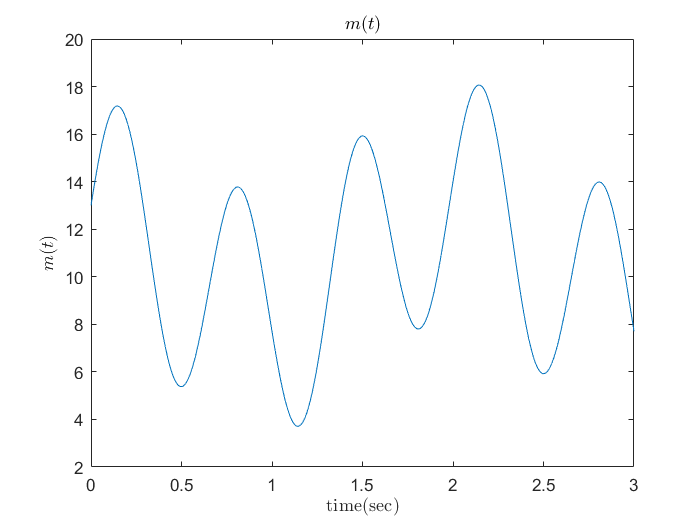

step = 1/50000;
t = 0:step:3;
m_t = 10 + 5* sin(3 * pi * t) + 3 * (cos(pi * t) .^3) + sin(pi * t / 4);
figure
plot(t,m_t);
title('$m(t)$','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m(t)$','Interpreter','latex');

**Sampling to Shape Discontinuous Signal**

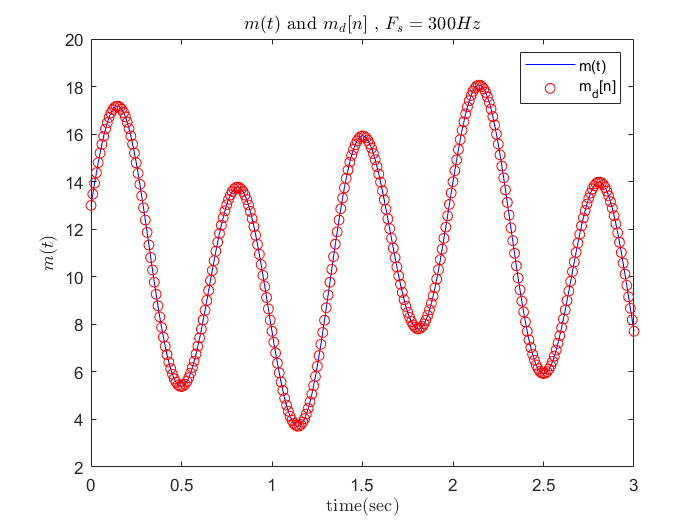

fs = 500;
ts = 1 / fs;
m_s = m_t(1:fs:length(m_t));
n = 0:1:length(m_s)-1;
figure
plot(t,m_t,'b',t(1:fs:length(m_t)),m_s,'ro');
title('$m(t)$ and $m_d[n]$ , $F_s=300Hz$','Interpreter','latex');
legend('m(t)','m_d[n]');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m(t)$','Interpreter','latex');

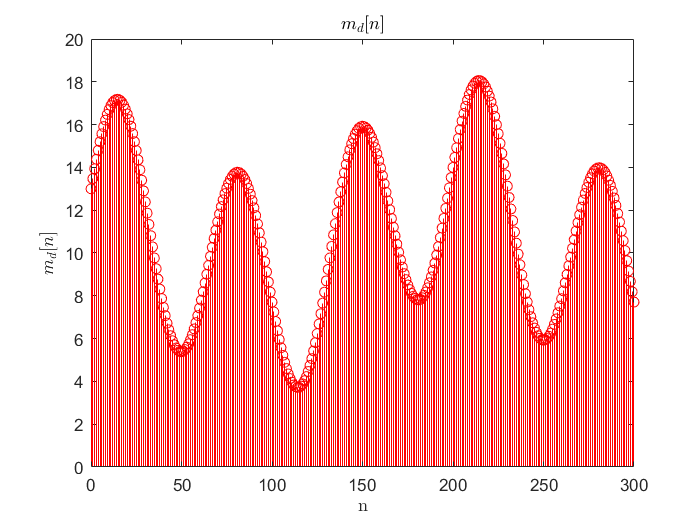


figure
stem(n,m_s ,'r');
title('$m_d[n]$','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$m_d[n]$','Interpreter','latex');

**Quantization mode**

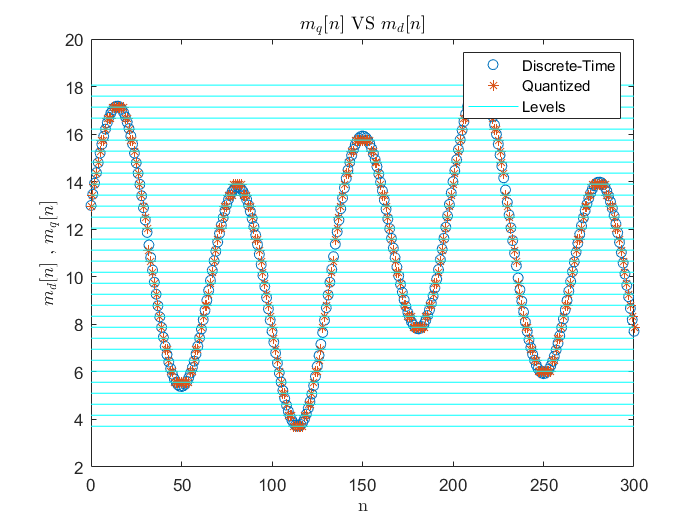

q = 32;
q_lev = linspace(min(m_s),max(m_s),q);
rows = q_lev'*ones(1,length(n));
m_q = q_lev(end) * ones(1,length(n));
for i = 1:length(n)
    for j = 1:q-1
        delta_q = q_lev(j + 1) - q_lev(j);
        if(m_s(i)>=q_lev(j) && m_s(i) < q_lev(j + 1))
            image = floor(2 * (m_s(i) - q_lev(j)) / delta_q);
        m_q(i) = q_lev(j) + image * (q_lev(j + 1) - q_lev(j));
        end
    end
end
figure
plot(n,m_s,'o',n,m_q,'*',n,rows,'c');
legend('Discrete-Time','Quantized','Levels');
title('$m_q[n]$ VS $m_d[n]$','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$m_d[n]$ , $m_q[n]$','Interpreter','latex');

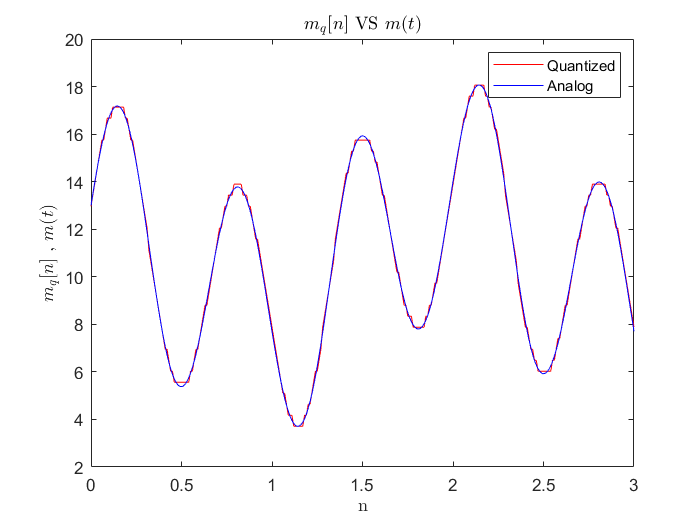


figure
plot(n/100,m_q,'r',t,m_t,'b');
legend('Quantized','Analog');
title('$m_q[n]$ VS $m(t)$','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$m_q[n]$ , $m(t)$','Interpreter','latex');

**Digitalize the Quantized Signal**

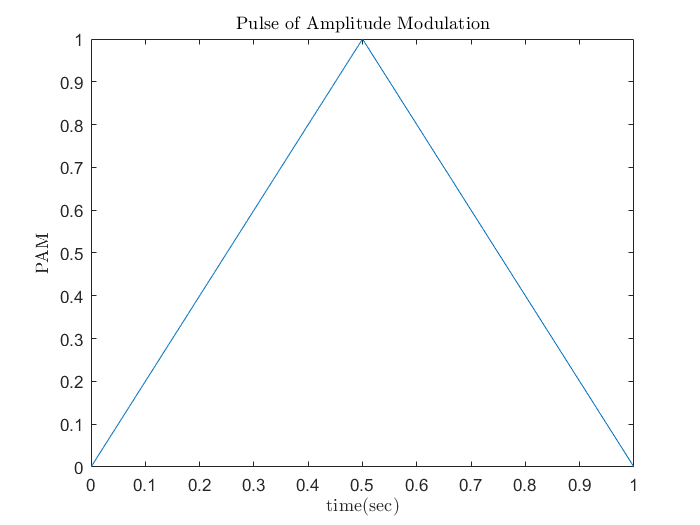

fs_pu = 1000;
ts_pu = 1 / fs_pu;
t_pulse = ts_pu:ts_pu:1;
PAM = importdata('C:\UT_Semester_7\Communication Systems\p.mat');
figure
plot(t_pulse,PAM);
title('Pulse of Amplitude Modulation','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('PAM','Interpreter','latex');

PAM_Egy = sum(PAM.^2)

PAM_Egy = 333.3340

**Pulse Code Modulation**

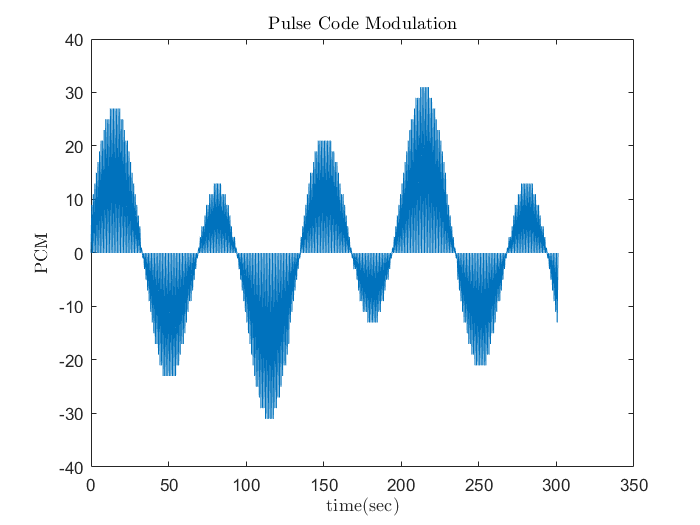

Dig = 0:1:q-1;
dom = -31:2:31;
len = length(PAM);
gry = dec2bin(bin2gray(Dig','pam',32),5);
PCM = [];
pcm_t = [];
gry_pcm = [];
lev_gry = [q_lev;Dig;dom];
for i = 1:length(m_q)
 j = find(lev_gry(1,:) == m_q(i));
 PCM((i - 1) * len + 1:i * len) = PAM * lev_gry(3,j);
 pcm_t((i - 1) * len + 1:i * len) = (i - 1) + t_pulse;
 gry_pcm = [gry_pcm ; gry(j,:)];
end
plot(pcm_t,PCM);
title('Pulse Code Modulation','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('PCM','Interpreter','latex');

**Indicate Transformed Signal in Receiver**

SNR_dB = 20;
SNR = 10 ^ (SNR_dB / 10);
N = length(PCM);
S = sum(PCM.^2) / N;
variance= S/SNR

variance = 0.9322

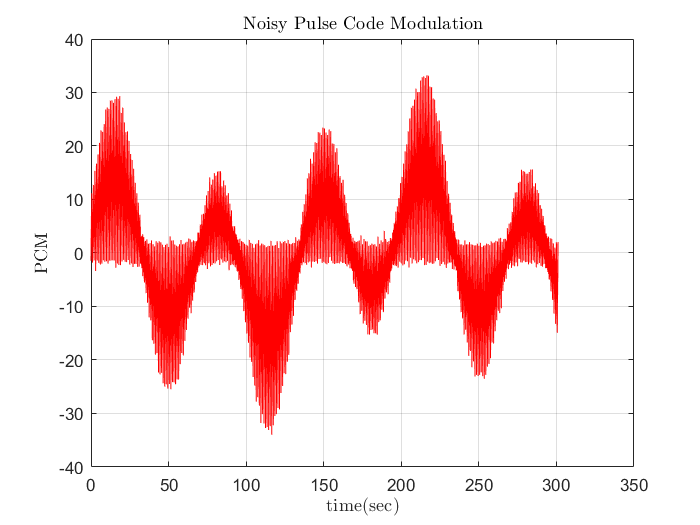

mu = 0;
noise = normrnd(mu,sqrt(variance),[1 length(PCM)]);
noise_pcm = noise + PCM;
figure
plot(pcm_t,noise_pcm,'r');
grid on
title('Noisy Pulse Code Modulation','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('PCM','Interpreter','latex');

**Decoding Phase**

mu_eng = zeros(1,length(noise_pcm) * ts_pu);
for i = 1:length(mu_eng)
    mu_eng(i) = sum(PAM.*noise_pcm((i-1)*len+1:i*len));
end
A = mu_eng/PAM_Egy;

**Find level of Quantization: (Reconstruction of Quantized Signal)**

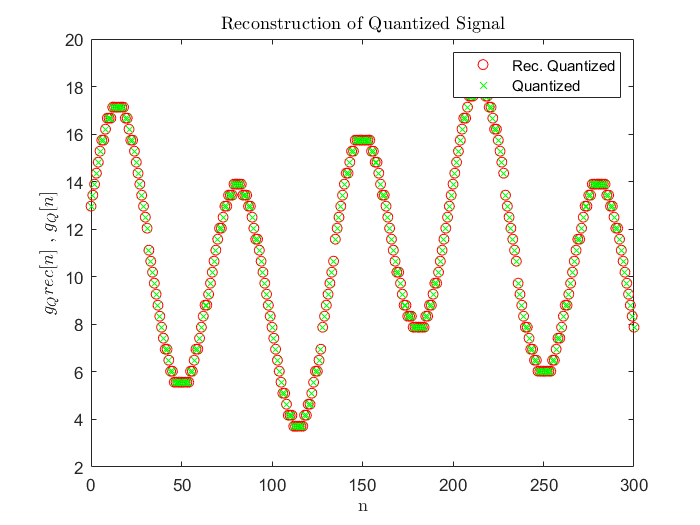

Norm_A = zeros(1,length(A));
rec_qua = zeros(1,length(A));
for i = 1:length(A)
    for m = 1:1:q - 1
        dA = lev_gry(3,m + 1) - lev_gry(3,m);
        if(A(i) >= lev_gry(3,m) && A(i) <= lev_gry(3,m + 1))
            image = floor(2 * (A(i) - lev_gry(3,m)) / dA);
            Norm_A(i) = lev_gry(3,m) + image * (lev_gry(3,m + 1) - lev_gry(3,m));
        elseif(A(i) > lev_gry(3,end))
            Norm_A(i) = lev_gry(3,end);
        elseif(A(i) < lev_gry(3,1))
            Norm_A(i) = lev_gry(3,1);
        end
    end
    j = find(lev_gry(3,:) == Norm_A(i));
    rec_qua(i) = lev_gry(1,j);
end
figure
plot(n, rec_qua, 'ro', n, m_q, 'gx');
legend('Rec. Quantized','Quantized');
title('Reconstruction of Quantized Signal','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$g_Qrec[n]$ , $g_Q[n]$','Interpreter','latex');

m_diff = sum(rec_qua ~= m_q);
fprintf('the error is %d%%', m_diff);

the error is 0%